load concreteIntensityFeatures.mat

concreteTableTest = extractConcreteFeatures(dsTest)

concreteTableTest = 200×4 table
     label        imgName      intensityAvg    intensitySTD
    ________    ___________    ____________    ____________

    No Crack    "00171.jpg"      0.82787         0.049307  
    No Crack    "00628.jpg"      0.62594           0.0262  
    No Crack    "00735.jpg"      0.78222         0.021937  
    No Crack    "00767.jpg"      0.82462         0.034151  
    No Crack    "01358.jpg"       0.7357         0.045503  
    No Crack    "01524.jpg"      0.75095         0.024884  
    No Crack    "01926.jpg"      0.67091          0.03601  
    No Crack    "02032.jpg"      0.78295         0.025778  
    No Crack    "02115.jpg"      0.71614         0.026794  
    No Crack    "02442.jpg"      0.67127         0.032604  
    No Crack    "02583.jpg"      0.77903         0.092346  
    No Crack    "02722.jpg"      0.55886         0.

dsUnlabeledConcrete = imageDatastore("C:\Users\efpla\OneDrive\Masaüstü\Computer Programming\MATLAB\Computer Vision\Computer Vision for Engineering and Science\Data\Data\MathWorks Images\Unlabeled Concrete","LabelSource","foldernames")

dsUnlabeledConcrete =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\Data\MathWorks Images\Unlabeled Concrete\Concrete_01.JPG';
                              ' ...\Data\Data\MathWorks Images\Unlabeled Concrete\Concrete_02.JPG';
                              ' ...\Data\Data\MathWorks Images\Unlabeled Concrete\Concrete_03.JPG'
                               ... and 7 more
                              }
                     Folders: {
                              ' ...\Data\Data\MathWorks Images\Unlabeled Concrete'
                              }
                      Labels: [Unlabeled Concrete; Unlabeled Concrete; Unlabeled Concrete ... and 7 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
 

concreteTableUnlabeled = extractConcreteFeatures(dsUnlabeledConcrete)

concreteTableUnlabeled = 10×4 table
          label                imgName         intensityAvg    intensitySTD
    __________________    _________________    ____________    ____________

    Unlabeled Concrete    "Concrete_01.JPG"      0.63753         0.080235  
    Unlabeled Concrete    "Concrete_02.JPG"      0.64298         0.047085  
    Unlabeled Concrete    "Concrete_03.JPG"      0.75704         0.038011  
    Unlabeled Concrete    "Concrete_04.JPG"      0.61691         0.083861  
    Unlabeled Concrete    "Concrete_05.JPG"      0.53104         0.023639  
    Unlabeled Concrete    "Concrete_06.JPG"      0.65584          0.11181  
    Unlabeled Concrete    "Concrete_07.JPG"       0.7543         0.059445  
    Unlabeled Concrete    "Concrete_08.JPG"       0.6318         0.034312  
    Unlabeled Concrete    "Concrete_09.JPG"      0.61845          0

concreteTableUnlabeled.Prediction = ConcreteCrackClassifier.predictFcn(concreteTableUnlabeled)

concreteTableUnlabeled = 10×5 table
          label                imgName         intensityAvg    intensitySTD    Prediction
    __________________    _________________    ____________    ____________    __________

    Unlabeled Concrete    "Concrete_01.JPG"      0.63753         0.080235       Crack    
    Unlabeled Concrete    "Concrete_02.JPG"      0.64298         0.047085       No Crack 
    Unlabeled Concrete    "Concrete_03.JPG"      0.75704         0.038011       No Crack 
    Unlabeled Concrete    "Concrete_04.JPG"      0.61691         0.083861       Crack    
    Unlabeled Concrete    "Concrete_05.JPG"      0.53104         0.023639       No Crack 
    Unlabeled Concrete    "Concrete_06.JPG"      0.65584          0.11181       Crack    
    Unlabeled Concrete    "Concrete_07.JPG"       0.7543         0.059445

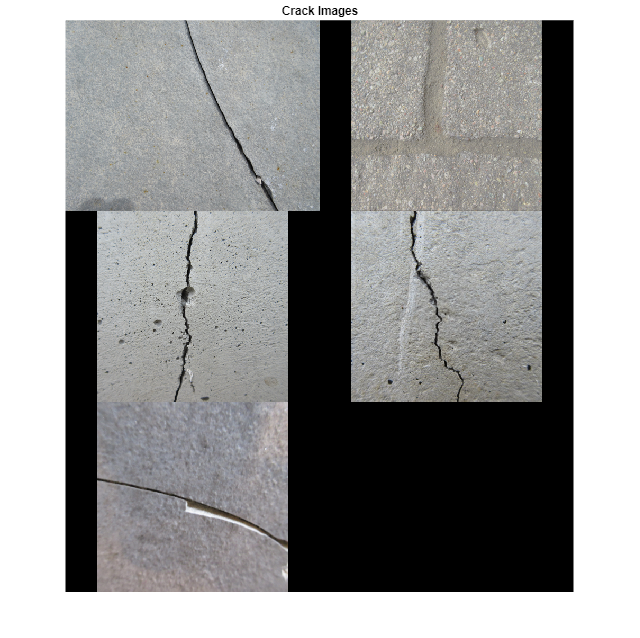

montage(concreteTableUnlabeled.imgName(concreteTableUnlabeled.Prediction == "Crack"))
title("Crack Images")

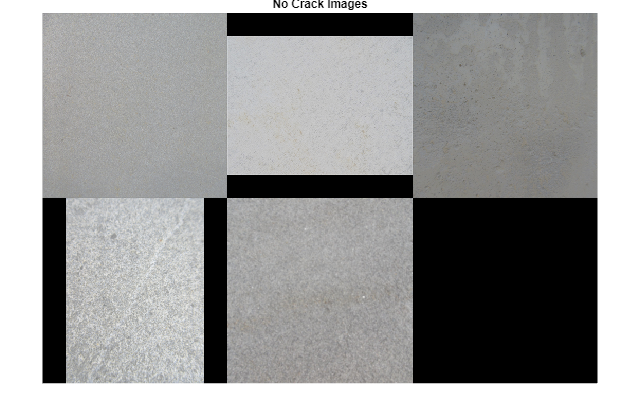

montage(concreteTableUnlabeled.imgName(concreteTableUnlabeled.Prediction == "No Crack"))
title("No Crack Images")